# DIFERENCIALNE ROVNICE VIAC DIMENZII

## --- Eulerova metóda ---

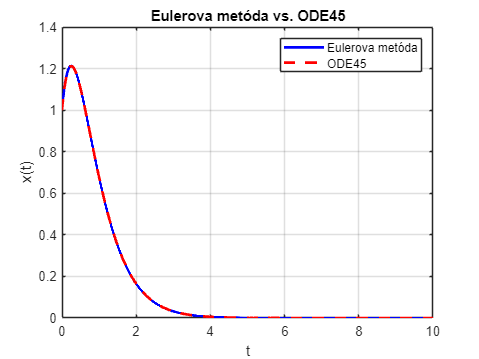


clc; clear; close all

a = 0;
b = 10;
h = 0.001;             % krok
x0 = [1; 2];       % príklad vektorového stavu
t = a:h:b;
n = length(t);

x_Euler = zeros(length(x0), n);
x_Euler(:,1) = x0;

for i = 1:n-1
    a1 = odeFcn(t(i), x_Euler(:,i));
    x_Euler(:,i+1) = x_Euler(:,i) + h*a1;
end

[t_ode, x_ode] = ode45(@odeFcn, [a b], x0);

plot(t, x_Euler(1,:), 'b-', 'LineWidth', 2); hold on
plot(t_ode, x_ode(:,1), 'r--', 'LineWidth', 2);
grid on
xlabel('t')
ylabel('x(t)')
title('Eulerova metóda vs. ODE45')
legend('Eulerova metóda', 'ODE45')

## --- Lichobežníková metóda ---

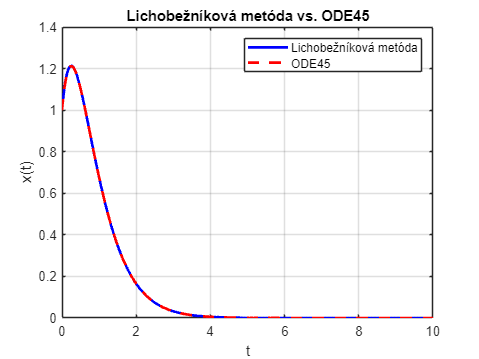


clc; clear; close all

a = 0;
b = 10;
h = 0.01;
x0 = [1; 2];
t = a:h:b;
n = length(t);

x_trap = zeros(length(x0), n);
x_trap(:,1) = x0;

for i = 1:n-1
    a1 = odeFcn(t(i), x_trap(:,i));
    a2 = odeFcn(t(i)+h, x_trap(:,i)+h*a1);
    x_trap(:,i+1) = x_trap(:,i) + (h/2)*(a1 + a2);
end

[t_ode, x_ode] = ode45(@odeFcn, [a b], x0);

plot(t, x_trap(1,:), 'b-', 'LineWidth', 2); hold on
plot(t_ode, x_ode(:,1), 'r--', 'LineWidth', 2);
grid on
xlabel('t')
ylabel('x(t)')
title('Lichobežníková metóda vs. ODE45')
legend('Lichobežníková metóda', 'ODE45')

## --- Runge-Kutta 4. rádu ---

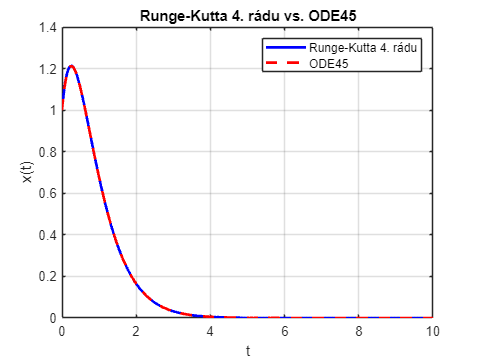


clc; clear; close all

a = 0;
b = 10;
h = 0.01;
x0 = [1; 2];
t = a:h:b;
n = length(t);

x_RK = zeros(length(x0), n);
x_RK(:,1) = x0;

for i = 1:n-1
    a1 = odeFcn(t(i), x_RK(:,i));
    a2 = odeFcn(t(i)+h/2, x_RK(:,i)+h/2*a1);
    a3 = odeFcn(t(i)+h/2, x_RK(:,i)+h/2*a2);
    a4 = odeFcn(t(i)+h, x_RK(:,i)+h*a3);
    x_RK(:,i+1) = x_RK(:,i) + (h/6)*(a1 + 2*a2 + 2*a3 + a4);
end

[t_ode, x_ode] = ode45(@odeFcn, [a b], x0);

plot(t, x_RK(1,:), 'b-', 'LineWidth', 2); hold on
plot(t_ode, x_ode(:,1), 'r--', 'LineWidth', 2);
grid on
xlabel('t')
ylabel('x(t)')
title('Runge-Kutta 4. rádu vs. ODE45')
legend('Runge-Kutta 4. rádu', 'ODE45')